# 34763 Autonomous Marine Robotics - Training Session 2 - Learning models from data

## Set up the Import Options and import the data

clear all
clc

opts = delimitedTextImportOptions("NumVariables", 39);

% Specify range and delimiter
opts.DataLines = [42, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["posix", "x_mocap", "y_mocap", "z_mocap", "qx_mocap", "qy_mocap", "qz_mocap", "qw_mocap", "ax", "ay", "az", "wx", "wy", "wz", "ax_c", "ay_c", "az_c", "qx", "qy", "qz", "qw", "pwm0", "pwm1", "pwm2", "pwm3", "pwm4", "pwm5", "N0", "N1", "N2", "N3", "N4", "N5", "Fx", "Fy", "Fz", "Mx", "My", "Mz"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
filename = "CIRCLE_combined.csv"; % file containing the experimental data
Data = readtable(filename, opts)

Data = 987×39 table
      posix       x_mocap    y_mocap     z_mocap     qx_mocap     qy_mocap     qz_mocap    qw_mocap       ax         ay         az          wx             wy          wz         ax_c       ay_c        az_c           qx             qy           qz          qw        pwm0      pwm1      pwm2      pwm3      pwm4      pwm5       N0        N1         N2         N3         N4         N5         Fx        

## Clear temporary variables

clear opts

## Select data for learning surge model

% Generate time vector converting from POSIX time into elapsed number of
% seconds since the start time of the experiment. The POSIX time is the number 
% of seconds that have elapsed since the Unix epoch, excluding leap
% seconds.

% Convert POSIX time vector to datetime array
dateTimeArray = datetime(Data.posix, 'ConvertFrom', 'posixtime');

% Calculate elapsed time since the first element in seconds
elapsedTimeSinceFirstElement = seconds(dateTimeArray - dateTimeArray(1));

% Display the result
disp(elapsedTimeSinceFirstElement);

         0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000
    1.1000
    1.2000
    1.3000
    1.4000
    1.5000
    1.6000
    1.7000
    1.8000
    1.9000
    2.0000
    2.1000
    2.2000
    2.3000
    2.4000
    2.5000
    2.6000
    2.7000
    2.8000
    2.9000
    3.0000
    3.1000
    3.2000
    3.3000
    3.4000
    3.5000
    3.6000
    3.7000
    3.8000
    3.9000
    4.0000
    4.1000
    4.2000
    4.3000
    4.4000
    4.5000
    4.6000
    4.7000
    4.8000
    4.9000
    5.0000
    5.1000
    5.2000
    5.3000
    5.4000
    5.5000
    5.6000
    5.7000
    5.8000
    5.9000
    6.0000
    6.1000
    6.2000
    6.3000
    6.4000
    6.5000
    6.6000
    6.7000
    6.8000
    6.9000
    7.0000
    7.1000
    7.2000
    7.3000
    7.4000
    7.5000
    7.6000
    7.7000
    7.8000
    7.9000
    8.0000
    8.1000
    8.2000
    8.3000
    8.4000
    8.5000
    8.6000
    8.7000
    8.8000
    8.9000
    9.0000

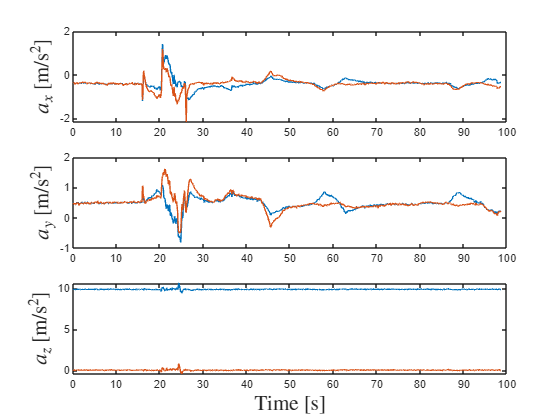

time = elapsedTimeSinceFirstElement; % time vector in seconds

% Let us familiarize with some of the motion data

% Linear accelerations and angular rates are measured by the 
% Inertial Measurement Unit (IMU) onboard the BlueROV. 
ax = Data.ax; % acceleration in the forward direction
ax_c = Data.ax_c; % acceleration in the forward direction compensated for gravity
ay = Data.ay; % acceleration in the lateral direction
ay_c = Data.ay_c; % acceleration in the lateral direction compensated for gravity
az = Data.az; % acceleration in the vertical direction
az_c = Data.az_c; % acceleration in the vertical direction compensated for gravity

figure, subplot(3,1,1), plot(time,ax,time,ax_c)
ylabel('$a_x$ [m/s$^2$]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,2), plot(time,ay,time,ay_c)
ylabel('$a_y$ [m/s$^2$]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,3), plot(time,az,time,az_c)
ylabel('$a_z$ [m/s$^2$]','FontSize',16,'FontName','Times','Interpreter','latex')
xlabel('Time [s]','FontSize',16,'FontName','Times','Interpreter','latex')

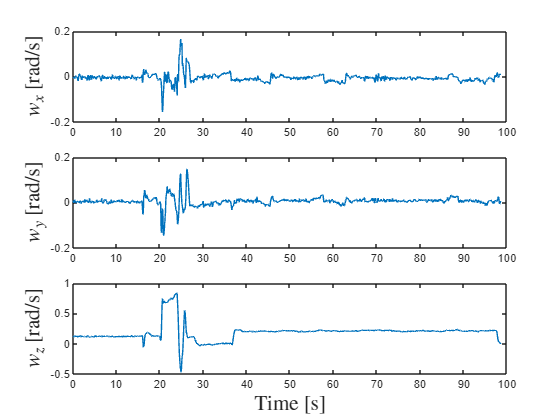

wx = Data.wx; % roll rate
wy = Data.wy; % pitch rate
wz = Data.wz; % yaw rate

figure, subplot(3,1,1), plot(time,wx)
ylabel('$w_x$ [rad/s]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,2), plot(time,wy)
ylabel('$w_y$ [rad/s]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,3), plot(time,wz)
ylabel('$w_z$ [rad/s]','FontSize',16,'FontName','Times','Interpreter','latex')
xlabel('Time [s]','FontSize',16,'FontName','Times','Interpreter','latex')

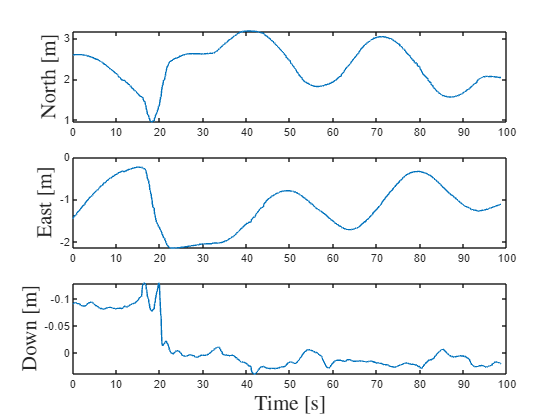


% The linear positions along the X, Y and Z axes are measured through the 
% OptiTrack Motion Capture System, which provides information about the 
% translational motion of the BlueROV with respect to an inertial reference frame.

% Define the position vector [North East Down]
North = Data.x_mocap;
East = Data.y_mocap;
Down = Data.z_mocap;

figure, figure, subplot(3,1,1), plot(time,North)
ylabel('North [m]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,2), plot(time,East)
ylabel('East [m]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,3), plot(time,Down)
set(gca,'YDir', 'reverse')
ylabel('Down [m]','FontSize',16,'FontName','Times','Interpreter','latex')
xlabel('Time [s]','FontSize',16,'FontName','Times','Interpreter','latex')

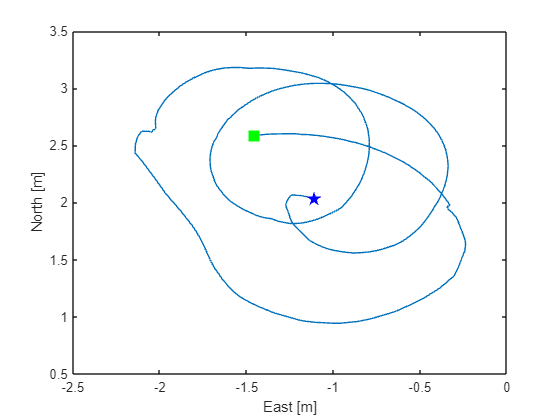

% Plot path on the North-East plane
figure, plot(East,North)
ylabel('North [m]')
xlabel('East [m]')

% Highlight initial position
hold on; % Retain current plot when adding new plots
plot(East(1), North(1), 's', 'MarkerSize', 10, 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');

% Highlight final position
plot(East(end), North(end), 'p', 'MarkerSize', 10, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
hold off;

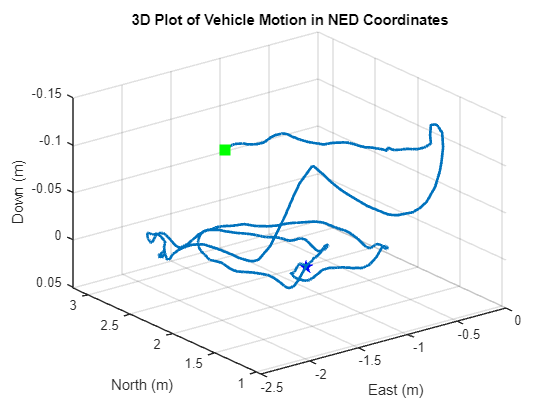


% Create 3D plot
figure;
plot3(East, North, Down, 'LineWidth', 2);
set(gca,'ZDir', 'reverse')

% Highlight initial position
hold on; % Retain current plot when adding new plots
plot3(East(1), North(1), Down(1), 's', 'MarkerSize', 10, 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');

% Highlight final position
plot3(East(end), North(end), Down(end), 'p', 'MarkerSize', 10, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
hold off;

% Label axes
xlabel('East (m)');
ylabel('North (m)');
zlabel('Down (m)');
title('3D Plot of Vehicle Motion in NED Coordinates');

% Set view for better 3D visualization
view(3); % Set the default 3D view
grid on; % Turn on the grid for better readability


% The angular rotation around the X, Y and Z axes are also measured through the 
% OptiTrack Motion Capture System. The rotations are provided in the
% so-called quaternion representation, which utilizes the vector format q =
% [qw, qx, qy, qz] to represent a ZYX rotation sequence.

% Define a quaternion [qw qx qy qz]
qw = Data.qw_mocap;
qx = Data.qx_mocap;
qy = Data.qy_mocap;
qz = Data.qz_mocap;
quat = [qw qx qy qz]; % Example quaternion

% Convert quaternion to Euler angles using the default 'ZYX' rotation sequence
eulZYX = quat2eul(quat);

% Display the Euler angles
disp('Euler angles (ZYX rotation sequence):');

Euler angles (ZYX rotation sequence):


disp(rad2deg(eulZYX)); % the function rad2deg converts the angle from radians to degrees

   80.1337    0.5020   -2.5132
   81.6885    0.4201   -2.6163
   81.7380    0.4181   -2.6276
   83.0129    0.4301   -2.5346
   83.6225    0.4089   -2.5273
   83.8219    0.4066   -2.5385
   83.8641    0.3495   -2.5680
   85.2931    0.4219   -2.5630
   85.4779    0.4093   -2.5692
   87.0877    0.4212   -2.5782
   87.1959    0.4537   -2.6154
   88.3984    0.4756   -2.6506
   89.0906    0.3743   -2.6366
   89.4378    0.3529   -2.6145
   89.4799    0.3822   -2.6381
   89.5219    0.4116   -2.6617
   90.9288    0.4045   -2.6146
   92.2960    0.5663   -2.1148
   92.7917    0.6045   -2.4458
   93.5329    0.4143   -2.6905
   94.2431    0.5824   -2.7593
   95.0261    0.6249   -2.7709
   95.0681    0.5820   -2.7885
   96.3639    0.5942   -2.6907
   96.9844    0.6346   -2.5006
   97.7027    0.5562   -2.7370
   97.7699    0.5385   -2.7656
   97.8371    0.5209   -2.7942
   99.1802    0.6361   -2.6382
  100.4740    0.6766   -2.7847
  101.0417    0.7288   -2.6885
  101.5797    0.7806   -2.6328
  102.52

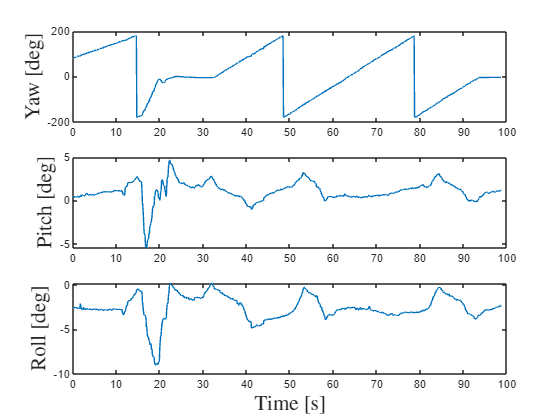

figure, figure, subplot(3,1,1), plot(time,rad2deg(eulZYX(:,1)))
ylabel('Yaw [deg]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,2), plot(time,rad2deg(eulZYX(:,2)))
ylabel('Pitch [deg]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,1,3), plot(time,rad2deg(eulZYX(:,3)))
ylabel('Roll [deg]','FontSize',16,'FontName','Times','Interpreter','latex')
xlabel('Time [s]','FontSize',16,'FontName','Times','Interpreter','latex')

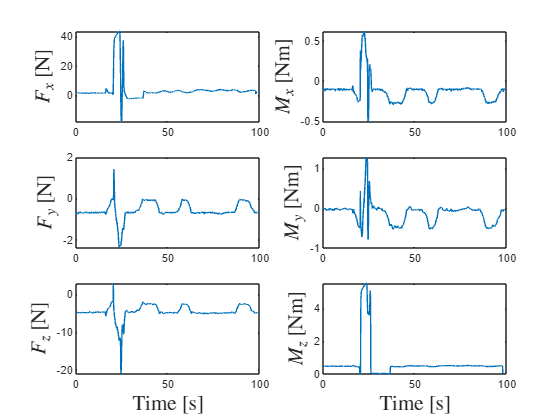

% The linear and angular motions are due to forces and moments generated by
% the thrusters.

Fx = Data.Fx; % Force along the longitudinal axis of the BlueROV
Fy = Data.Fy; % Force along the lateral axis of the BlueROV
Fz = Data.Fz; % Force along the vertical axis of the BlueROV
Mx = Data.Mx; % Moment around the longitudinal axis of the BlueROV (it generates roll rotation)
My = Data.My; % Moment around the lateral axis of the BlueROV (it generates pitch rotation)
Mz = Data.Mz; % Moment around the vertical axis of the BlueROV (it generates yaw rotation)

figure, figure, subplot(3,2,1), plot(time,Fx)
ylabel('$F_x$ [N]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,2,3), plot(time,Fy)
ylabel('$F_y$ [N]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,2,5), plot(time,Fz)
ylabel('$F_z$ [N]','FontSize',16,'FontName','Times','Interpreter','latex')
xlabel('Time [s]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,2,2), plot(time,Mx)
ylabel('$M_x$ [Nm]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,2,4), plot(time,My)
ylabel('$M_y$ [Nm]','FontSize',16,'FontName','Times','Interpreter','latex')
subplot(3,2,6), plot(time,Mz)
ylabel('$M_z$ [Nm]','FontSize',16,'FontName','Times','Interpreter','latex')
xlabel('Time [s]','FontSize',16,'FontName','Times','Interpreter','latex')

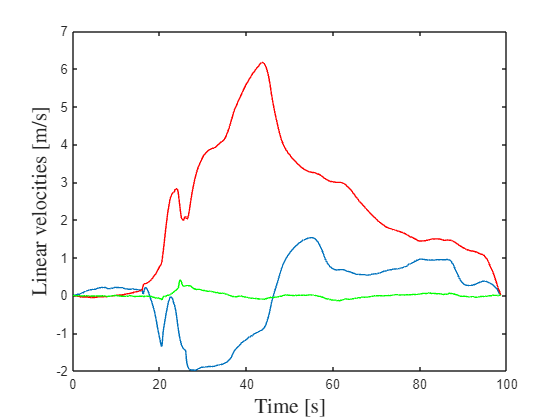

% Linear velocity are not measured during the experiments. An easy way to
% obtain the linear velocities along the X, Y and Z axis is to perform the
% numerical integration of the measured accelerations ax, ay, and az. Due
% to the presence of systematic and stochastic errors in the measured
% accelerations, this approach may lead to erroneous values for the
% computed velocities. A more robust approach to the computation of linear 
% velocities is the use of so-called Kalman filtering. 

% Compute an estimate of the surge/sway/heave velocity by perform numerical integration 
% using the trapezoidal rule. Remove bias from measured accelerations
ax_c = ax_c - mean(ax_c);
surge_speed = cumtrapz(time,ax_c);
ay_c = ay_c - mean(ay_c);
sway_speed = cumtrapz(time,ay_c);
az_c = az_c - mean(az_c);
heave_speed = cumtrapz(time,az_c);

% Display the result
figure, plot(time,surge_speed,time,sway_speed,'r',time,heave_speed,'g')
ylabel('Linear velocities [m/s]','FontSize',16,'FontName','Times','Interpreter','latex')
xlabel('Time [s]','FontSize',16,'FontName','Times','Interpreter','latex')